# Linear Control Design II - Group Work Problem Module 9

## Description		

The airplane model is to be extended by adding a second input: The aileron angle $\delta_a$ as shown on figure 1. The roll angle$\varphi$ is also added to the output vector. 

  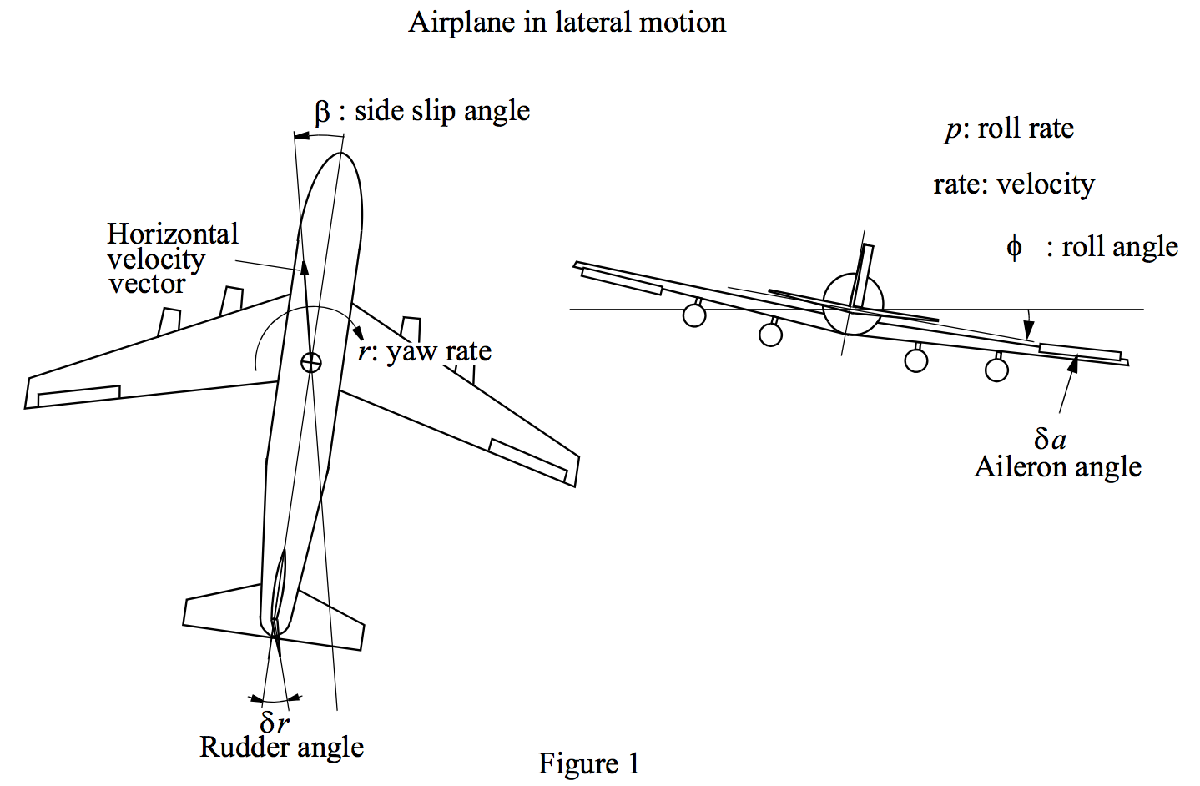

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:


$$\pmatrix{ \dot{\beta} \cr \dot{r} \cr \dot{p} \cr \dot{\varphi} } = \pmatrix{ -0.0558 &\ -0.9968 &\ 0.0802 &\ 0.0415 \cr 0.5980 &\ -0.1150 &\ -0.0318 &\ 0 \cr -3.0500 &\ 0.3880 &\ -0.4650 &\ 0 \cr 0 &\ 0.0805 &\ 1 &\ 0 } \pmatrix{ \beta \cr r \cr p \cr \varphi } + \pmatrix{ 0.00729 &\ 10^{-5} \cr -0.47500 &\ 0.123\cr 0.15300 &\ 1.063\cr 0 &\ 0} \pmatrix{ \delta r \cr \delta a }$$

$$y = \pmatrix{ 0 \ 1 \ 0 \ 0 \cr 0 \ 0 \ 0 \ 1 } \pmatrix{ \beta \cr r \cr p \cr \varphi}$$


where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), $\delta_r$ is the rudder deflection (rad) and $\delta_a$ is the aileron angle (rad).

format short g; clear all; close all; clc;

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0];
B = [0.00729   1e-5; 
    -0.475     0.123; 
     0.153     1.063;     
     0         0];
C = [0 1 0 0;
     0 0 0 1];
D = zeros(2,2);

% Define state-space system:
sys_ss = ss(A,B,C,D)


sys_ss =
 
  A = 
            x1       x2       x3       x4
   x1  -0.0558  -0.9968   0.0802   0.0415
   x2    0.598   -0.115  -0.0318        0
   x3    -3.05    0.388   -0.465        0
   x4        0   0.0805        1        0
 
  B = 
            u1       u2
   x1  0.00729    1e-05
   x2   -0.475    0.123
   x3    0.153    1.063
   x4        0        0
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   0   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



**Problem 1  **Is the system controllable and observable?

*Use the controllability and observability matrices *$\mathbf{M_c}$* and *$\mathbf{M_o}$* (Matlab functions ctrb and obsv). How would you test whether *$\mathbf{M_c}$* has 4 linearly independent columns?*

*Also use the test with the left and the right eigenvectors (first part of PBH-test, i.e. the criteria CC3 and OC3) and the diagonal test (CC4 and OC4).*

**Solution****:**

% Your solution goes here:
Mc = ctrb(A,B);
Mo = obsv(A,C);
if rank(Mc) == size(A,1)
    disp('The system is controllable')
    if rank(Mo) == size(A,1)
        disp('The system is observable')
    else
        disp('The system is not observable')
    end
else
    disp('The system is not controllable')
    if rank(Mo) == size(A,1)
        disp('The system is observable')
    else
        disp('The system is not observable')
    end
end

The system is controllable


The system is observable


[V,L,W] = eig(A);
ctrlb = ~sum(sum(W'*B==0,2)>1);
obsvb = ~sum(sum(C *V==0,1)>1);
if ctrlb
    disp('The system is controllable')
    if obsvb
        disp('The system is observable')
    else
        disp('The system is not observable')
    end
else
    disp('The system is not controllable')
    if obsvb
        disp('The system is observable')
    else
        disp('The system is not observable')
    end
end

The system is controllable


The system is observable


P = inv(V);
Ct = C*inv(P);
Bt = P*B;
obsvb = ~sum(sum(Ct == 0,1)>1);
ctrlb = ~sum(sum(Bt == 0,2)>1);
if ctrlb
    disp('The system is controllable')
    if obsvb
        disp('The system is observable')
    else
        disp('The system is not observable')
    end
else
    disp('The system is not controllable')
    if obsvb
        disp('The system is observable')
    else
        disp('The system is not observable')
    end
end

The system is controllable


The system is observable


**Problem 2  **Find the 4 transfer functions and determine the 4 sets of poles and zeros. 

**Solution:**

% Your solution goes here:
G = minreal(tf(sys_ss))


G =
 
  From input 1 to output...
          -0.475 s^3 - 0.2479 s^2 - 0.1187 s - 0.05633
   1:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
                  0.1148 s^2 - 0.2004 s - 1.373
   2:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
  From input 2 to output...
          0.123 s^3 + 0.03026 s^2 + 0.08238 s + 0.04195
   1:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
                  1.073 s^2 + 0.2317 s + 1.024
   2:  ---------------------------------------------------
       s^4 + 0.6358 s^3 + 0.9389 s^2 + 0.5116 s + 0.003674
 
Continuous-time transfer function.



for i = 1:2
    for o = 1:2
        po{i,o} = pole(G(i,o));
        zo{i,o} = zero(G(i,o));
    end
end

disp(po{1}),disp(po{2}),disp(po{3}),disp(po{4})

    -0.032935 +    0.94665i
    -0.032935 -    0.94665i
     -0.56265 +          0i
    -0.007278 +          0i

    -0.032935 +    0.94665i
    -0.032935 -    0.94665i
     -0.56265 +          0i
    -0.007278 +          0i

    -0.032935 +    0.94665i
    -0.032935 -    0.94665i
     -0.56265 +          0i
    -0.007278 +          0i

    -0.032935 +    0.94665i
    -0.032935 -    0.94665i
     -0.56265 +          0i
    -0.007278 +          0i



disp(zo{1}),disp(zo{2}),disp(zo{3}),disp(zo{4})

     -0.49808 +          0i
    -0.011893 +    0.48779i
    -0.011893 -    0.48779i

       4.4398
       -2.694

      0.10121 +    0.86618i
      0.10121 -    0.86618i
     -0.44845 +          0i

     -0.10797 +    0.97082i
     -0.10797 -    0.97082i



**Problem 3  **Set up a detailed Simulink model of the airplane. Base the model on figure 2.3 in the textbook. Note: One can use the MatrixGain-block as well as the usual Gain-block, but be sure that it is set up for matrix-multiplication. 

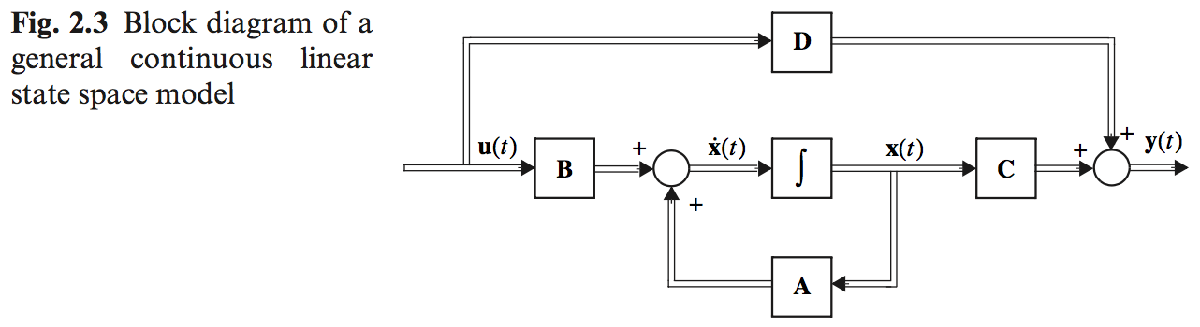

**Solution:**

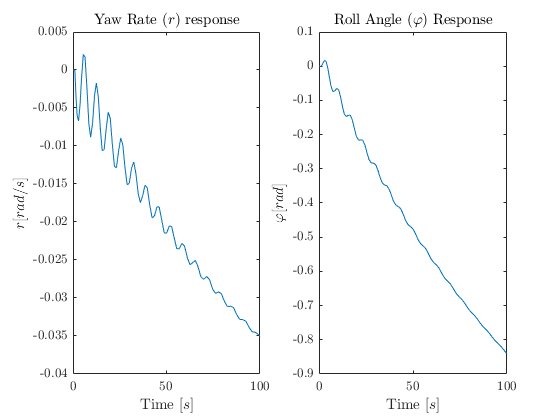

simSwitch = 1;
x0 = [0 0 0 0];
u0 = [1 1]'.*pi/180;
u = u0;
modl = 'Mdl_9';
% modl = 'M9_Q3_Lat747'
sim(modl,100)

figure
title('')
subplot(1,2,1)
plot(tout,yout.signals.values(:,1)),xlabel('Time $[s]$'),ylabel('$r [rad/s]$'),title('Yaw Rate $(r)$ response')
subplot(1,2,2)
plot(tout,yout.signals.values(:,2)),xlabel('Time $[s]$'),ylabel('$\varphi [rad]$'),title('Roll Angle $(\varphi)$ Response')

**Problem 4  **Find the 4 step responses (use the angle 1° for both inputs) and plot them in a 2 by 2 array using Matlab’s subplot-function. 

**Solution:**

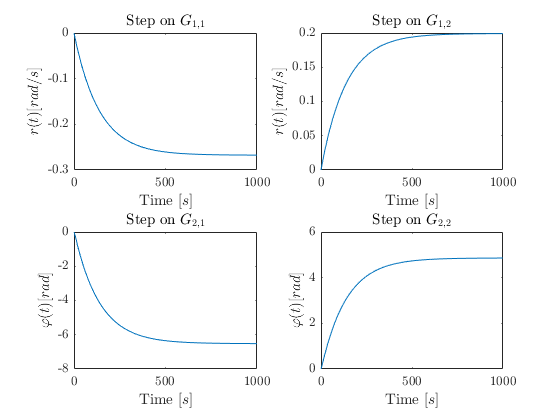

% Your solution goes here:
ttl = {'Step on $G_{1,1}$','Step on $G_{1,2}$','Step on $G_{2,1}$','Step on $G_{2,2}$'};
yl = {'$r(t) [rad/s]$','$\varphi (t) [rad]$'};
figure
for i = 1:2
    for j = 1:2
        subplot(2,2,2*(i-1)+j)
        [y,t] = step(G(i,j)*pi/180,1000);
        plot(t,y),xlabel('Time $[s]$'),ylabel(yl(i)),title(ttl(2*(i-1)+j))
    end
end

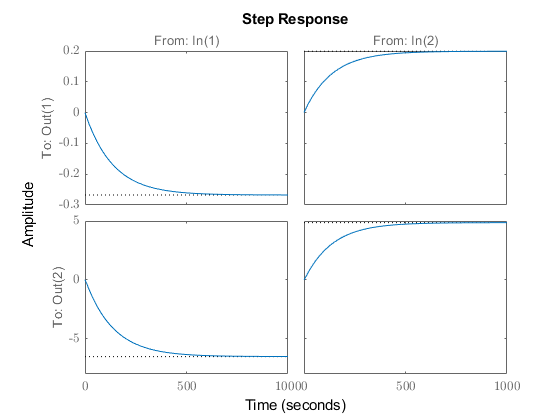

figure
step(G*pi/180,1000)

**Problem 5**  Last, simulate the response of the linear system by using the function on figure 2 at both inputs, but one at a time.

Is it possible to change the airplane’s heading by manipulating the ailerons only? 

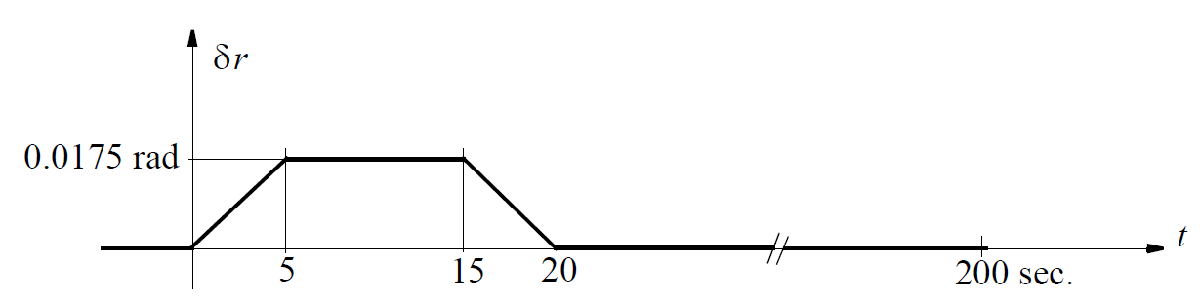	

**Solution:**

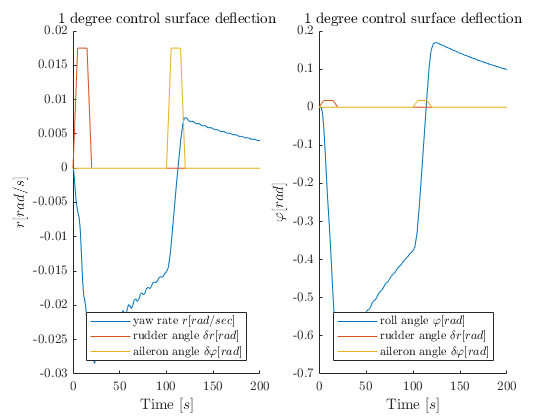

% Your solution goes here:
clear

A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0];
B = [0.00729   1e-5; 
    -0.475     0.123; 
     0.153     1.063;     
     0         0];
C = [0 1 0 0;
     0 0 0 1];
D = zeros(2,2);

t = 0:0.1:200;
U1 = t(1:50)*0.0175/5;
U2 = t(51:150)*0+0.0175;
U3 = 0.0175 - U1;
U4 = t(201:end)*0;
U5 = t(1:1000)*0;
U6 = t(1201:end)*0;
Us1 = [U1 U2 U3 U4];
Us2 = [U5 U1 U2 U3 U6];
inp1 = [t' Us1' Us2'];
inp2 = [t' Us2' Us1'];

modl = 'Mdl_9';
x0 = [0 0 0 0];
u0 = [0 0];
simSwitch = -1;
sim(modl,200,[],inp1)
figure;
subplot(1,2,1)
hold on
plot(tout,yout.signals.values(:,1))
% plot(tout,yout.signals.values(:,2))
plot(t,inp1(:,2),t,inp1(:,3))
xlabel('Time $[s]$'),ylabel('$r [rad/s]$'),title('1 degree control surface deflection')
legend('yaw rate $r [rad/sec]$', 'rudder angle $\delta r [rad]$',...
    'aileron angle $\delta \varphi [rad]$',...
    'Location','southeast')
subplot(1,2,2)
hold on
% plot(tout,yout.signals.values(:,1))
plot(tout,yout.signals.values(:,2))
plot(t,inp1(:,2),t,inp1(:,3))
xlabel('Time $[s]$'),ylabel('$\varphi [rad]$'),title('1 degree control surface deflection')
legend('roll angle $\varphi [rad]$', 'rudder angle $\delta r [rad]$',...
    'aileron angle $\delta \varphi [rad]$',...
    'Location','southeast')


% sim(modl,200,[],inp2)
% figure
% hold on
% plot(tout,yout.signals.values(:,1))
% plot(tout,yout.signals.values(:,2))
% plot(t,inp2(:,2),t,inp2(:,3))
% xlabel('Time $[s]$'),ylabel('$r [rad/s]$ and $\varphi [rad]$'),title('Response to Aileron deflection 1 degree')
% 
% xlabel('Time $[s]$'),ylabel('$r [rad/s]$ and $\varphi [rad]$'),title('Response to Rudder deflection 1 degree')
% legend('yaw rate $r [rad/sec]$','roll angle $\varphi [rad]$',...
%     'rudder angle $\delta r [rad]$', 'aileron angle $\delta \varphi [rad]$',...
%     'Location','southeast')
